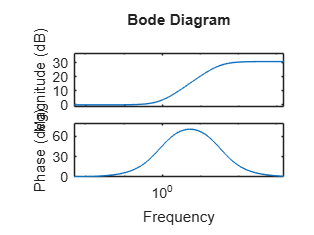

s = tf('s');
K = 15;
G =  2/(s*(s+1)*(s+3));
Gc = (1.107*s+1)/(0.03167*s+1);
Gc2 = (0.2988*s+1)/(0.04132*s+1);
Gb = K*G*Gc*Gc2;


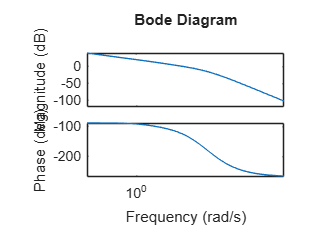

bode(Gb)


step(feedback(G,1))
hold

Current plot held


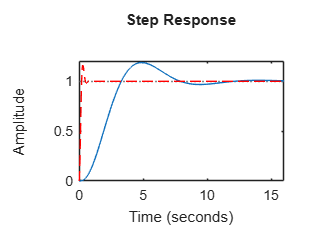

step(feedback(Gb,1),'--red')